# Tutorial: EPI Distortion Correction

# Part 1: Static Distortion Correction = Using a Single $\Delta B_0$ Field Map

## Computational Steps Overview:

- Defining Inputs: Gradient Echo Field Map and EPI data

- Calculating Voxel Shift Map from Gradient Echo Field Map Phase Difference Data

- Coregistering Voxel Shift Map to EPI

- Unwarping 

- Quality Assurance

## Step 1 - Defining Inputs

working_dir = 'D:\PostDoc_FIL_WCHN\Conferences\ISMRM_2023\DDC_EPI\Tutorial\data_EPI_DC_Tutorial' ;
romeo_path = 'D:\PostDoc_FIL_WCHN\software\mritools\bin';
cd(working_dir)

Let's have a look at the available data.

**3T Gradient Echo Field Map (GEFM):** magnitude and phase difference (1.5x1.5x2.0 ${\textrm{mm}}^3$) 

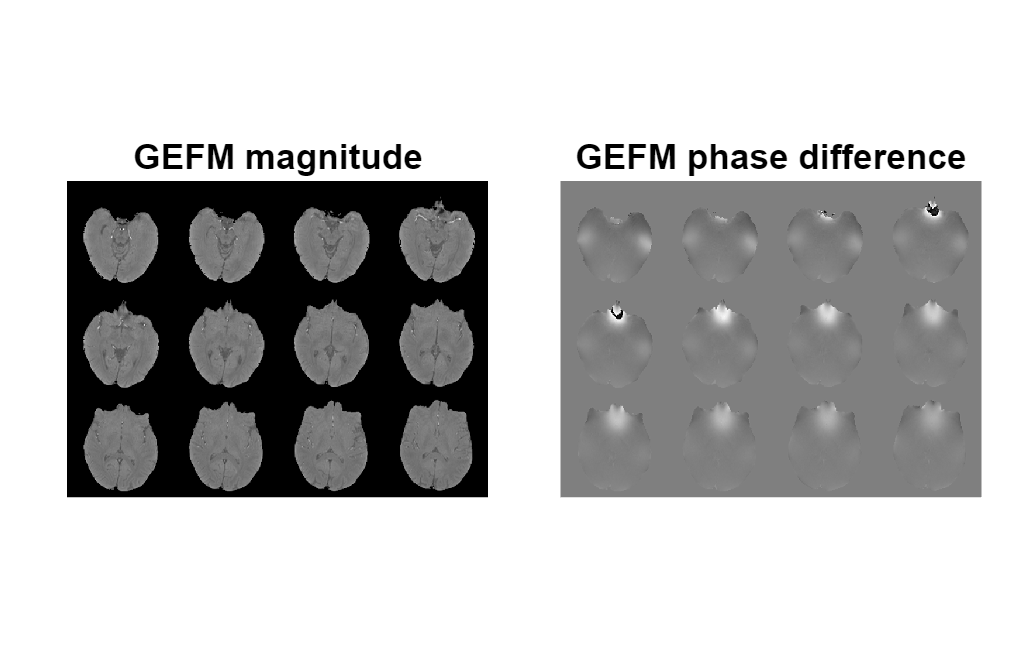

view = 'axial'; 'sagittal' ; % pick a view

GEFM_mag = nifti('GEFM_mag.nii').dat(:,:,:) ;
GEFM_phdiff = nifti('GEFM_ph.nii').dat(:,:,:) ;

t = tiledlayout(1,2);
t.TileSpacing = 'compact';
t.Padding = 'compact';

nexttile
if strcmp(view, 'sagittal')
    montage(mat2gray(permute(flip(GEFM_mag(end/2-6:end/2+5,:,:,:),3),[3 2 4 1]))) % sagittal view
elseif strcmp(view, 'axial')
    montage(mat2gray(permute(flip(GEFM_mag(:,:,end/2-15:end/2-4,:),2),[2 1 4 3]))) % axial view
end
title('GEFM magnitude','FontSize',16)
nexttile
if strcmp(view, 'sagittal')
    montage(mat2gray(permute(flip(GEFM_phdiff(end/2-6:end/2+5,:,:,:),3),[3 2 4 1]))) % sagittal view
elseif strcmp(view, 'axial')
    montage(mat2gray(permute(flip(GEFM_phdiff(:,:,end/2-15:end/2-4,:),2),[2 1 4 3]))) % axial view
end
title('GEFM phase difference', 'FontSize',16)

**3T 2D Gradient Echo EPI data:** multi-volume magnitude data (1.5x1.5x2.0 ${\textrm{mm}}^3$):

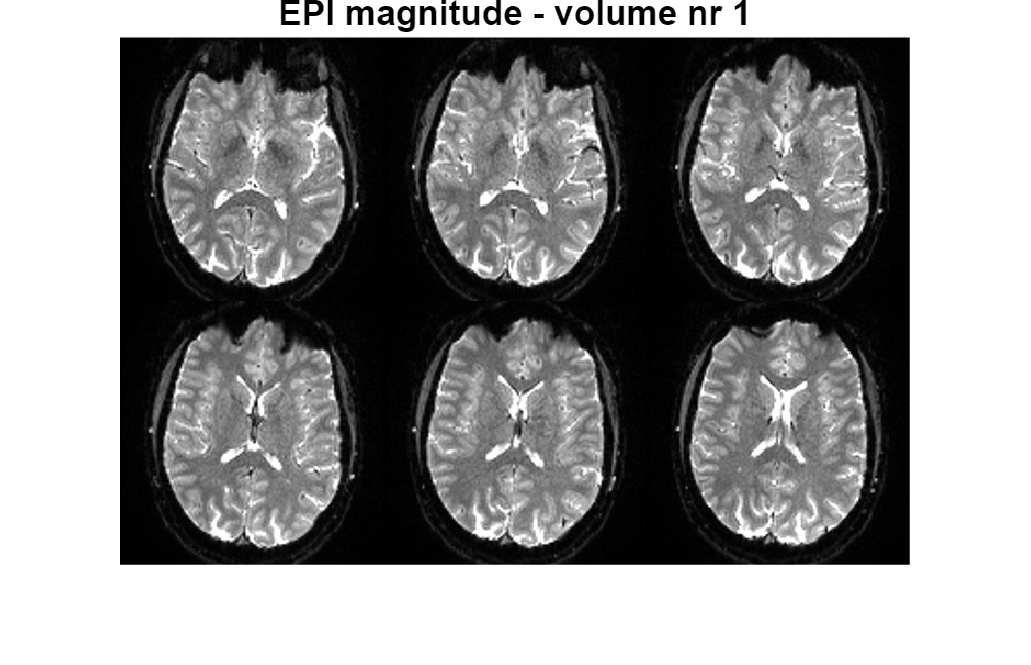

vol_nr = 1 ; % pick a volume number
view = 'axial';'sagittal' ;   % pick a view

EPI = nifti(fullfile(working_dir,'EPI','mag',sprintf('mag_%02.f.nii',vol_nr))).dat(:,:,:) ;
figure('Position', [0 0 1000 600]);
if strcmp(view, 'sagittal')
    montage(mat2gray(permute(flip(EPI(end/2-2:end/2+3,:,:,:),3),[3 2 4 1]),[0 1500])); % sagital view
elseif strcmp(view, 'axial')
    montage(mat2gray(permute(flip(EPI(:,:,end/2-6:end/2-1),2),[2 1 4 3]),[0 1500])); % axial view
end
title(sprintf('EPI magnitude - volume nr %i', vol_nr),'FontSize',16);

## Step 2 - Calculating Voxel Shift Map from GEFM Phase Difference Data

We will do:

    A. Phase Unwrapping 

    B. Field Map Calculation

    C. Field Map Extrapolation

    D. Voxel Shift Map Calculation

### A. Phase Unwrapping

Examples of phase unwrapping algorithms: PRELUDE (FSL) [1], BEST PATH [2], or ROMEO [3].

Some of them recquire that the phase is in $\left\lbrack 0\;2\pi \right)$range, i.e. in radian. 

Our GEFM phase has the following range of values (in this case it's a rough estimate the data were masked beforehand - best perform on unmasked data):

[GEFM_ph_min,GEFM_ph_max]  = bounds( GEFM_phdiff(:) , "all" )

GEFM_ph_min = -4082

GEFM_ph_max = 4090

We can rescale the GEFM phase data (if we need to) using:

GEFM_phdiff = 2*pi*(GEFM_phdiff - GEFM_ph_min)/(GEFM_ph_max-GEFM_ph_min) ;
[GEFM_ph_min,GEFM_ph_max]  = bounds( GEFM_phdiff(:) , "all" )

GEFM_ph_min = 0

GEFM_ph_max = 6.2832

But we will use ROMEO phase unwrapping which does the phase data rescaling for us:

system(sprintf('%s -p GEFM_ph.nii -m GEFM_mag.nii -o GEFM_ph_unwr.nii -v', fullfile(romeo_path, 'romeo')));

Phase loaded!
Mag loaded!
Phase offset correction with MCPC-3D-S turned off (only one echo)
Echoes are 1
TEs are 1
Calculate robustmask from magnitude, saved as mask.nii
individual unwrapping is false
echo 1 used as template
perform unwrapping...
unwrapping finished!


NB. ROMEO has won this year's ISMRM qMR Study Group open source challenge ;-)

Let's have a look if the data were properly unwrapped:

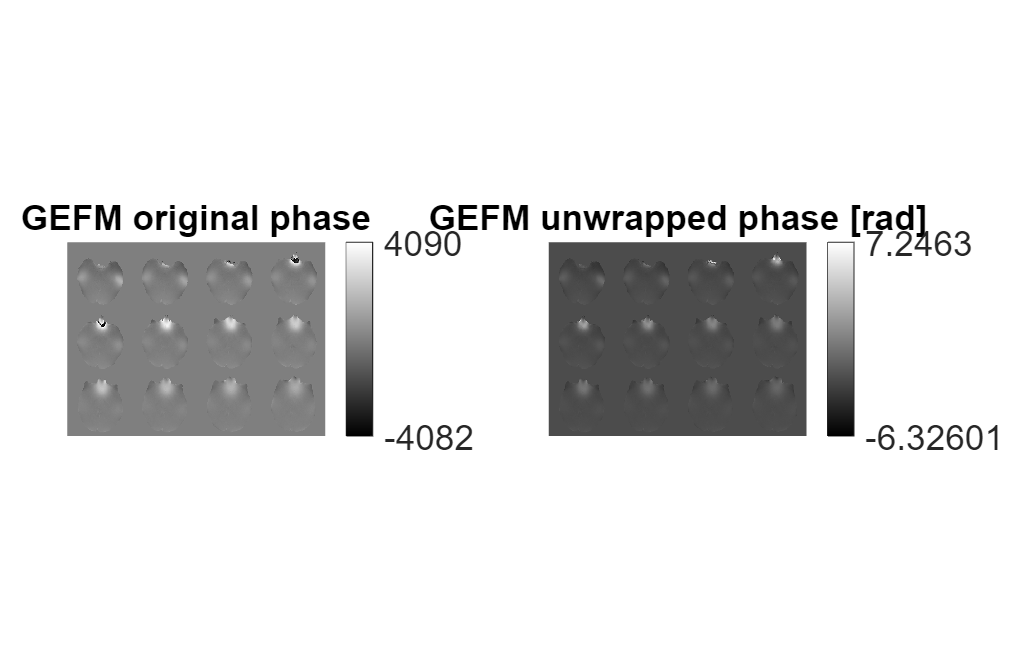

view = 'axial'; 'sagittal' ;  % pick a view

GEFM_phdiff = nifti('GEFM_ph.nii').dat(:,:,:) ;
GEFM_phdiff_unwr = nifti('GEFM_ph_unwr.nii').dat(:,:,:) ;

t = tiledlayout(1,2);
t.TileSpacing = 'compact';
t.Padding = 'compact';

nexttile
if strcmp(view, 'sagittal')
    montage(mat2gray(permute(flip(GEFM_phdiff(end/2-6:end/2+5,:,:,:),3),[3 2 4 1]))) % sagittal view
elseif strcmp(view, 'axial')
    montage(mat2gray(permute(flip(GEFM_phdiff(:,:,end/2-15:end/2-4,:),2),[2 1 4 3]))) % axial view
end
[GEFM_ph_min,GEFM_ph_max]  = bounds( GEFM_phdiff(:) , "all" );
colorbar('Ticks',[0 1],'TickLabels',{GEFM_ph_min,GEFM_ph_max},'FontSize',16);
title('GEFM original phase','FontSize',16)

nexttile
if strcmp(view, 'sagittal')
    montage(mat2gray(permute(flip(GEFM_phdiff_unwr(end/2-6:end/2+5,:,:,:),3),[3 2 4 1]))) % sagittal view
elseif strcmp(view, 'axial')
    montage(mat2gray(permute(flip(GEFM_phdiff_unwr(:,:,end/2-15:end/2-4,:),2),[2 1 4 3]))) % axial view
end
[GEFM_ph_min,GEFM_ph_max]  = bounds( GEFM_phdiff_unwr(:) , "all" );
colorbar('Ticks',[0 1],'TickLabels',{GEFM_ph_min,GEFM_ph_max},'FontSize',16);
title('GEFM unwrapped phase [rad]','FontSize',16);

### B. Field Map Calculation

Above, we unwrapped GEFM phase difference obtaining smooth map of phase variation in radian, $\Delta \theta$. 

We obtain a frequency shift map, $\Delta \omega_0$,  in Hertz by dividing the phase difference by $2\pi$and echo time difference:


$$\Delta \omega_0 =\frac{\Delta \theta }{2\pi \Delta \textrm{TE}}\left\lbrack \textrm{Hz}\right\rbrack$$
 

NB: $\Delta \omega_0$ is often referred in toolboxes as the Field Map. In FSL toolbox field map is actually given in [rad*Hz] unit, i.e. $\frac{\Delta \theta }{\Delta \textrm{TE}}$. 

An actual field inhomogeneity map in Tesla would be achieved as following:

$\Delta B_0 =\frac{\Delta \theta }{2\pi \gamma \Delta \textrm{TE}}\left\lbrack T\right\rbrack$, where $\gamma$is Gyromagnetic Ratio, but we don't need it for Voxel Shift Map calculation.

I will refer from now on to $\Delta \omega_0$ as the Field Map (e.g. GEFM).

GEFM_TEdiff = 2.46e-3;  % echo time difference in seconds
GEFM = GEFM_phdiff_unwr/(2*pi*GEFM_TEdiff) ;

Luckily, ROMEO can do this calculation for us by adding "-B" to previous ROMEO call:

system(sprintf('%s -p GEFM_ph.nii -m GEFM_mag.nii -o GEFM_ph_unwr.nii -v -B -t 2.46', fullfile(romeo_path, 'romeo')));

Phase loaded!
Mag loaded!
Phase offset correction with MCPC-3D-S set to monopolar
Phase offset correction with MCPC-3D-S turned off (only one echo)
Echoes are 1
TEs are 2.46
Calculate robustmask from magnitude, saved as mask.nii
individual unwrapping is false
echo 1 used as template
perform unwrapping...
unwrapping finished!


please mind $\Delta \textrm{TE}$=2.46 is in $\left\lbrack \textrm{ms}\right\rbrack$ and output $\Delta \omega_0$ is in $\left\lbrack \textrm{Hz}\right\rbrack$.

Equivalent in FSL would be (with $2\pi \cdot \Delta \omega_0$ is in $\left\lbrack \textrm{rad}\cdot \textrm{Hz}\right\rbrack$) :

%unix('fsl_prepare_fieldmap SIEMENS GEFM_ph.nii GEFM_mag.nii GEFM_FSL_radHz.nii 2.46');

### C. Field Map Extrapolation 

To improve accuracy of distortion correction at the brain boundaries we will extrapolate GEFM outside the masked area. Smoothn by D.Garcia provides robust extrapolation of 3D data with missing values [4].

GEFM = nifti('B0.nii').dat(:,:,:);
GEFM_extrap = GEFM;
GEFM_extrap(GEFM_extrap==0) = NaN;
GEFM_extrap = smoothn(GEFM_extrap, 1, 'robust');
createNifti(GEFM_extrap, 'GEFM_B0_extrap.nii', nifti('GEFM_ph.nii').mat)

Let's visually compare GEFM with and without extrapolation.

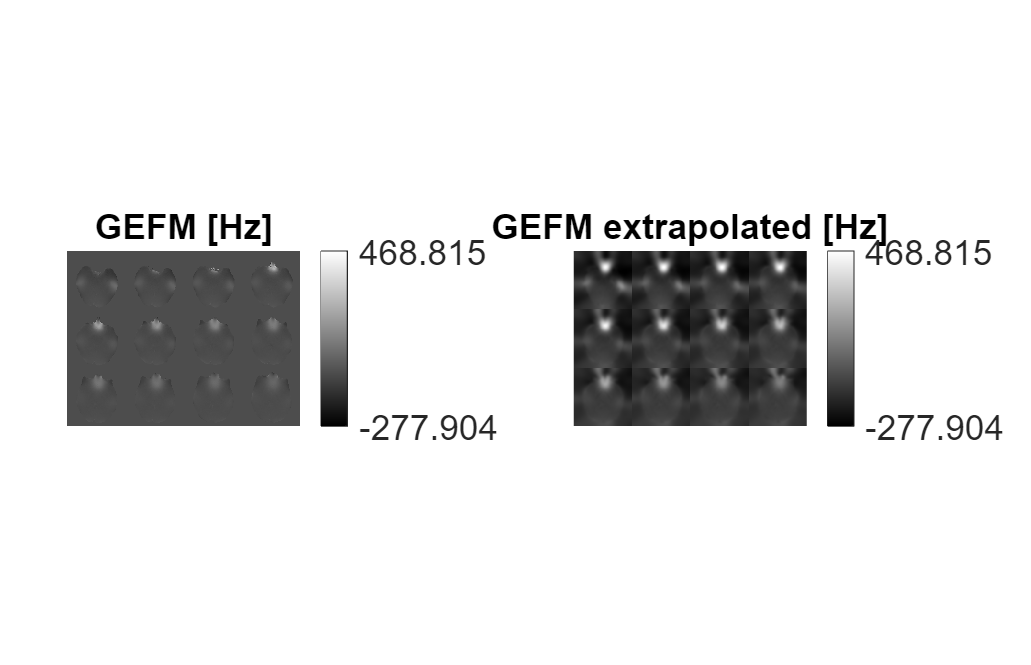

view = 'axial'; 'sagittal'; % pick a view

t = tiledlayout(1,2);
t.TileSpacing = 'compact';
t.Padding = 'compact';

nexttile
if strcmp(view, 'sagittal')
    montage(mat2gray(permute(flip(GEFM(end/2-6:end/2+5,:,:,:),3),[3 2 4 1]))) % sagittal view
elseif strcmp(view, 'axial')
    montage(mat2gray(permute(flip(GEFM(:,:,end/2-15:end/2-4,:),2),[2 1 4 3]))) % axial view
end
[GEFM_min,GEFM_max]  = bounds( GEFM(:) , "all" );
colorbar('Ticks',[0 1],'TickLabels',{GEFM_min,GEFM_max},'FontSize',16);
title('GEFM [Hz]','FontSize',16)

nexttile
if strcmp(view, 'sagittal')
    montage(mat2gray(permute(flip(GEFM_extrap(end/2-6:end/2+5,:,:,:),3),[3 2 4 1]))) % sagittal view
elseif strcmp(view, 'axial')
    montage(mat2gray(permute(flip(GEFM_extrap(:,:,end/2-15:end/2-4,:),2),[2 1 4 3]))) % axial view
end
colorbar('Ticks',[0 1],'TickLabels',{GEFM_min,GEFM_max},'FontSize',16);
title('GEFM extrapolated [Hz]','FontSize',16);

### D. Voxel Shift Map (VSM) Calculation

We want to know by how much we have to shift a particular voxel in EPI volume with a given signal intensity along the Phase Encoding (PE) direction.

Voxel Shift Map is proportional to Field Map is as following:


$$\textrm{VSM}=\frac{\Delta \omega_0 \cdot M_{\textrm{PE}} \cdot t_{\textrm{esp}} \cdot D_{\textrm{PE}} }{R}\;\left\lbrack \textrm{voxels}\right\rbrack$$


where:

$M_{\textrm{PE}}$ - Matrix size in PE direction

$t_{\textrm{esp}}$   - Echo spacing time, e.g. for trapezoid gradient form: 1 x flat top time + 2 x ramp up time

$R$     - Correction factor accounting any acceleration or segmentation reducing distortions, i.e.  $t_{\textrm{esp}}$/$R$ is the "effective echo spacing"

$D_{\textrm{PE}}$ - direction of phase encoding, it's either -1 or 1 depending on the convention. For our data -1 means acquisition in direction Anterior --> Posterior.

Please mind: $R$ does not account for partial Fourier, as this does not influence the effective echo spacing and distortions.

For this sample EPI dataset it will be:

M_PE = 128;
t_esp = 0.78*1e-3; % in seconds
R = 2; % this EPI was acquired with 2-fold in-plane acceleration
D_PE = -1; % phase encoding direction, in this case -1 for AP and 1 for PA

VSM = GEFM_extrap*M_PE*t_esp*D_PE/R ;

createNifti(VSM, 'VSM_SDC.nii', nifti('B0.nii').mat)

## Step 3 - Coregistering Voxel Shift Map to EPI

Corregister GEFM to the closest (in time) EPI volume.

For this dataset GEFM was acquired before the EPI run so we take the first volume (nr 01). 

We will use SPM12 [5] Coregister functionality embedded in the following wrapper (available in Supplementary Material):

coreg_GEFM2EPI('EPI/mag/mag_01.nii', 'GEFM_mag.nii', 'VSM_SDC.nii');



------------------------------------------------------------------------
04-Jun-2023 03:07:35 - Running job #1
------------------------------------------------------------------------
04-Jun-2023 03:07:35 - Running 'Coregister: Estimate & Reslice'

SPM12: spm_coreg (v7320)                           03:07:35 - 04/06/2023
Completed                               :          03:07:51 - 04/06/2023

SPM12: spm_reslice (v7141)                         03:07:51 - 04/06/2023
Completed                               :          03:07:52 - 04/06/2023
04-Jun-2023 03:07:52 - Done    'Coregister: Estimate & Reslice'
04-Jun-2023 03:07:52 - Done



Let's have a look at a volume of EPI and coregisterred VSM next to each other:

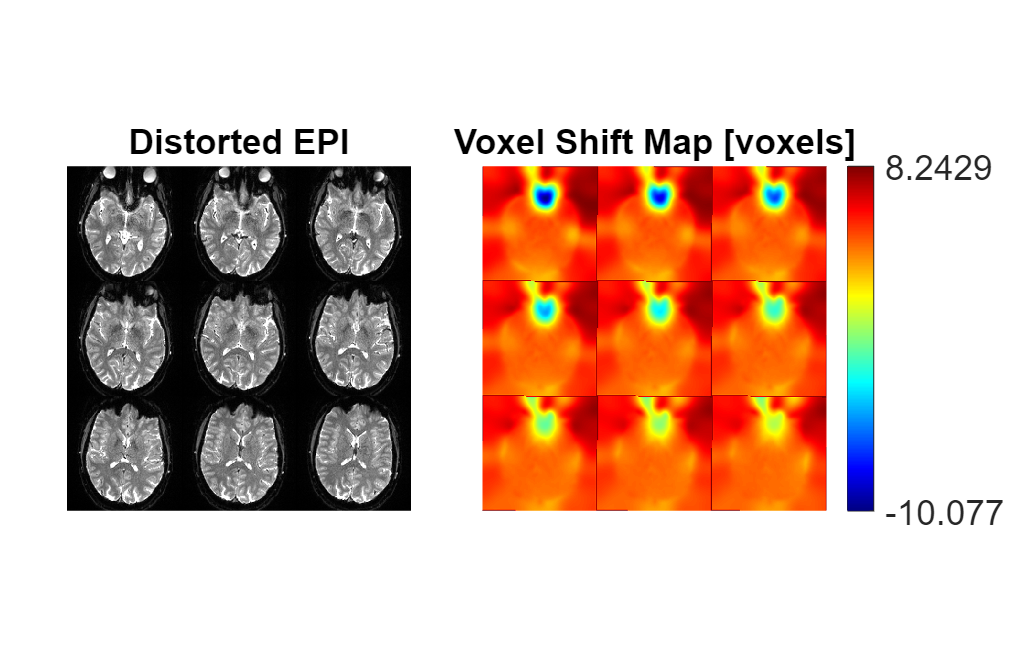

VSM = nifti('coreg2EPI_VSM_SDC.nii').dat(:,:,:);

t = tiledlayout(1,2);
t.TileSpacing = 'compact';
t.Padding = 'compact';

nexttile
montage(mat2gray(permute(flip(EPI(:,:,20:end-32),2),[2 1 4 3]),[0 1500]))
title('Distorted EPI','FontSize',16);

t = nexttile;
montage(mat2gray(permute(flip(VSM(:,:,20:end-32),2),[2 1 4 3])))
[VSM_min,VSM_max]  = bounds( VSM(:) , "all" );
colormap(t,jet)
colorbar('Ticks',[0 1],'TickLabels',{VSM_min,VSM_max},'FontSize',16);
title('Voxel Shift Map [voxels]','FontSize',16)

## Step 4 - Unwarping 

We will now apply VSM to shift voxel intensities along Phase Encoding direction and apply optional intensity correction:

- VSM values are noninteger, which means we have to interpolate the outcome back to uniform spatial grid. Here, for interpolation we will use spm_sample_vol function from SPM12 [5] and manual warp-field creation.

- Shifting voxel intensities using VSM does not correct for signal intensity changes caused by signal compression and stretching.

- A common method to correct voxel intensities is to multiply local Jacobian determinant of the VSM with the distortion corrected image. The Jacobian determinant reflects the relative local volume change when mapping from the undistorted to distorted spaces. Please mind that Jacobian determinan is based on field gradient, which reduces it's accuracy for low resolution GEFM acquisitions. Method to optimize Jacobian modulation, $J_{\textrm{Field}}$, can be found in Ref [6] for blip-reversed EPI acquisitions.

                
$$J_{\textrm{Field}} =1+\frac{\partial \textrm{VSM}\left(x,y,z\right)}{\partial y}$$


% creating warp field
% VSM must be added to the PE-direction of the warp field - here 2nd dim
[Mx, My, Mz] = size(EPI); % reading matrix size of the EPI
[x,y,z] = ndgrid(1:Mx,1:My,1:Mz); % creating rectangular grid for 3D space
F_warp = [x(:) y(:) z(:)]; % "identity" warp field, i.e. would not do anything to our data
F_warp(:,2) = F_warp(:,2) + reshape(VSM,[Mx*My*Mz,1]); % adding VSM to war field along PE-direction

% Jacobian determinant: We have significant distortions only in
% PE-direction, so J_field boils down to the calculation of a gradient in PE-direction
VSM_grad = (circshift(VSM,1,2)-circshift(VSM,-1,2))/2 ;
VSM_grad(~isfinite(VSM_grad))=0;
J_field = 1 + VSM_grad ;

Let's have a look at VSM and the Jacobian determinant together:

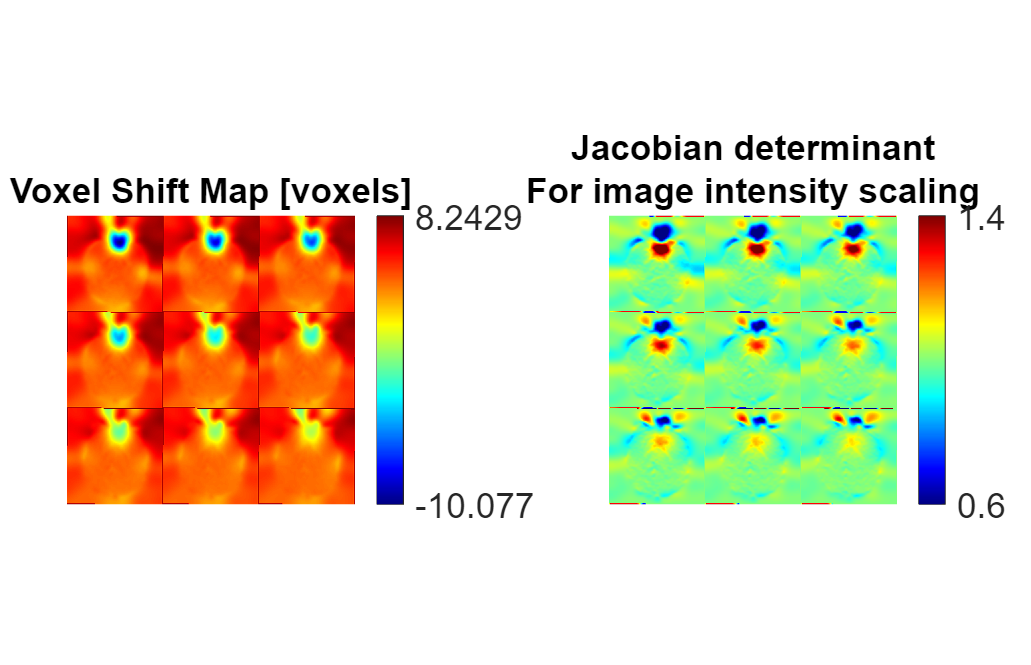

t = tiledlayout(1,2);
t.TileSpacing = 'compact';
t.Padding = 'compact';

nexttile
montage(mat2gray(permute(flip(VSM(:,:,20:end-32),2),[2 1 4 3])))
[VSM_min,VSM_max]  = bounds( VSM(:) , "all" );
colorbar('Ticks',[0 1],'TickLabels',{VSM_min,VSM_max},'FontSize',16);
title('Voxel Shift Map [voxels]','FontSize',16)

nexttile;
montage(mat2gray(permute(flip(J_field(:,:,20:end-32),2),[2 1 4 3]),[0.6 1.4]))
[J_min,J_max]  = bounds( J_field(:) , "all" );
colorbar('Ticks',[0 1],'TickLabels',{0.6,1.4},'FontSize',16);
title({'Jacobian determinant';'For image intensity scaling'},'FontSize',16)
colormap(jet)

% Unwarping volume by volume using calculated warp field
vol_nr = 1:54 ; % choose the range of volumes you want to unwrap
interp_method = -5 ; % 1 is trilinear, values > 0 are nth order polnomial, values < 0 are nth order sinc ...

mag_SDC = zeros(Mx,My,Mz) ;
for t = vol_nr

    EPI_file = fullfile('EPI/mag',sprintf('mag_%02.f.nii',t)) ;
    fprintf('Unwarping %s \n', EPI_file)

    EPI_SDC = reshape(spm_sample_vol(spm_vol(EPI_file),...
        F_warp(:,1),F_warp(:,2),F_warp(:,3),interp_method),[Mx,My,Mz]);

    EPI_SDC_file = fullfile('EPI/mag',sprintf('mag_%02.f_sdc.nii',t)) ;
    createNifti(EPI_SDC, EPI_SDC_file, nifti(EPI_file).mat)


    EPI_SDC_jac = EPI_SDC.*J_field ;

    EPI_SDC_file = fullfile('EPI/mag',sprintf('mag_%02.f_sdc_jac.nii',t)) ;
    createNifti(EPI_SDC_jac, EPI_SDC_file, nifti(EPI_file).mat)

end

Unwarping EPI\mag\mag_01.nii 
Unwarping EPI\mag\mag_02.nii 
Unwarping EPI\mag\mag_03.nii 
Unwarping EPI\mag\mag_04.nii 
Unwarping EPI\mag\mag_05.nii 
Unwarping EPI\mag\mag_06.nii 
Unwarping EPI\mag\mag_07.nii 
Unwarping EPI\mag\mag_08.nii 
Unwarping EPI\mag\mag_09.nii 
Unwarping EPI\mag\mag_10.nii 
Unwarping EPI\mag\mag_11.nii 
Unwarping EPI\mag\mag_12.nii 
Unwarping EPI\mag\mag_13.nii 
Unwarping EPI\mag\mag_14.nii 
Unwarping EPI\mag\mag_15.nii 
Unwarping EPI\mag\mag_16.nii 
Unwarping EPI\mag\mag_17.nii 
Unwarping EPI\mag\mag_18.nii 
Unwarping EPI\mag\mag_19.nii 
Unwarping EPI\mag\mag_20.nii 
Unwarping EPI\mag\mag_21.nii 
Unwarping EPI\mag\mag_22.nii 
Unwarping EPI\mag\mag_23.nii 
Unwarping EPI\mag\mag_24.nii 
Unwarping EPI\mag\mag_25.nii 
Unwarping EPI\mag\mag_26.nii 
Unwarping EPI\mag\mag_27.nii 
Unwarping EPI\mag\mag_28.nii 
Unwarping EPI\mag\mag_29.nii 
Unwarping EPI\mag\mag_30.nii 
Unwarping EPI\mag\mag_31.nii 
Unwarping EPI\mag\mag_32.nii 
Unwarping EPI\mag\mag_33.nii 
Unwarping 

## Step 5 - Quality Assurance (QA)

Don't assume distortion correction worked as intended, perform a tailored QA analysis.

Examples of possible QA procedures:

- Visual inspection 

              a. comparison before and after unwarping

              b. comparison of a reference structural scan with original, and corrected EPI data.

           2. Dice coefficient for grey matter masks.

Good examples of quality assurance can be found in Ref. [7].

**Visual inspection - before and after unwarping**

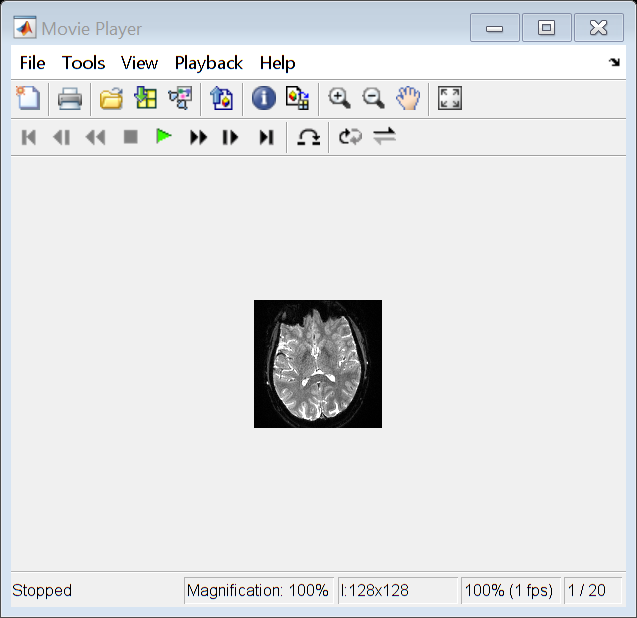

vol_nr = 1 ;
slice = 25 ;

EPI = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f.nii',vol_nr))).dat(:,:,:) ;
EPI_1vol_SDC = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_sdc.nii',vol_nr))).dat(:,:,:) ;
EPI_1vol_SDC_jac = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_sdc_jac.nii',vol_nr))).dat(:,:,:) ;

EPI_noDC_SDC = cat(3, flip(EPI(:,:,slice),2), flip(EPI_1vol_SDC(:,:,slice),2)) ;
EPI_noDC_SDC = repmat(EPI_noDC_SDC, [1 1 10]);
implay(mat2gray(imrotate(EPI_noDC_SDC,-90),[0 1500]), 1)

**Visual inspection - with and without Jacobian intensity correction**

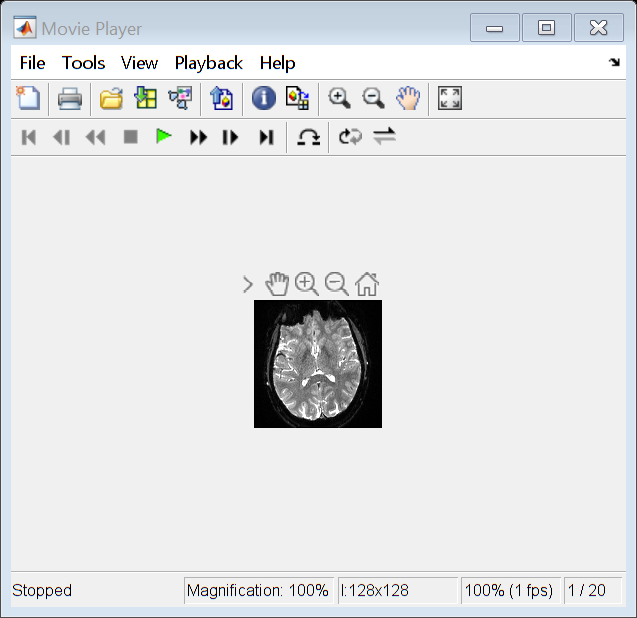

EPI_SDC_SDCjac = cat(3, flip(EPI_1vol_SDC(:,:,slice),2), flip(EPI_1vol_SDC_jac(:,:,slice),2)) ;
EPI_SDC_SDCjac = repmat(EPI_SDC_SDCjac, [1 1 10]);
implay(mat2gray(imrotate(EPI_SDC_SDCjac,-90),[0 1500]), 1)

**Visual inspection - structural vs EPI**

In this case as a structural scan a Gradient Echo was used with same resolution and TE (30ms) as EPI. 

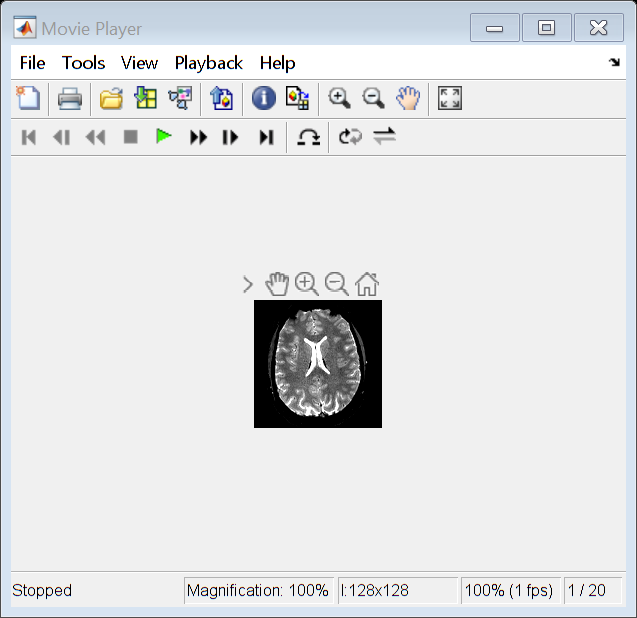

vol_nr = 1 ; % pick an EPI volume number
slice = 30 ; % pick a slice
view = 'axial'; 'saggital' ; % pick a view
DC_case = 'noDC' ;'SDC' ; % pick a case, 'SDC' = static distortion correction, 'noDC' = no correction

if strcmp(DC_case, 'noDC')
    EPI = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f.nii',vol_nr))).dat(:,:,:) ;
    structural = nifti(fullfile(working_dir, 'struct_coreg2EPI_mean_noDC.nii')).dat(:,:,:);
elseif strcmp(DC_case, 'SDC')
    EPI = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_sdc.nii',vol_nr))).dat(:,:,:) ;
    structural = nifti(fullfile(working_dir, 'struct_coreg2EPI_mean_SDC.nii')).dat(:,:,:);
end
structural(~isfinite(structural))=0;

if strcmp(view,'axial')
    EPI_SDC_structural = cat(3, mat2gray(squeeze(flip(EPI(:,:,slice),2)),[200 1500]), mat2gray(squeeze(flip(structural(:,:,slice),2)),[400 1500])) ;
    EPI_SDC_structural = repmat(EPI_SDC_structural, [1 1 10]);
elseif strcmp(view, 'sagittal')
    EPI_SDC_structural = cat(3, mat2gray(squeeze(flip(EPI(slice,:,:),3)),[200 1500]), mat2gray(squeeze(flip(structural(slice,:,:),3)),[400 1500])) ;
    EPI_SDC_structural = repmat(EPI_SDC_structural, [1 1 10]);
end

implay(imrotate(EPI_SDC_structural,-90), 1)

## Dice Coefficient

Dice coefficient = "overlap" of Gray Matter (GM) masks, i.e.

**dice = 2 (intersected GM region)/(sum of GM regions from image A and image B)**.

Let's load precalculated GM probability maps (SPM12 Segment tool) for structural reference and EPIs.

A wrapper for SPM12 Segment is provided in Supplementary material.

 We will threshold and binarize GM probability maps and calculate pair-wise Dice Coefficients:

GM_threshold = 0.5 ;

% loading precalculated GM probability maps:
struct_GM = nifti(fullfile(working_dir,'struct_GM_coreg2EPI_mean_noDC.nii')).dat(:,:,:);
struct_GM_SDC = nifti(fullfile(working_dir,'struct_GM_coreg2EPI_mean_SDC.nii')).dat(:,:,:);
struct_GM_SDCjac = nifti(fullfile(working_dir,'struct_GM_coreg2EPI_mean_SDC_jac.nii')).dat(:,:,:);
EPI_GM = nifti(fullfile(working_dir,'EPI/mag','c1mag_mean.nii')).dat(:,:,:) ;
EPI_GM_SDC = nifti(fullfile(working_dir,'EPI/mag','c1mag_sdc_mean.nii')).dat(:,:,:) ;
EPI_GM_SDCjac = nifti(fullfile(working_dir,'EPI/mag','c1mag_sdc_jac_mean.nii')).dat(:,:,:) ;

% creating GM masks:
struct_GM = imbinarize(struct_GM, GM_threshold);
struct_GM_SDC = imbinarize(struct_GM_SDC, GM_threshold);
struct_GM_SDCjac = imbinarize(struct_GM_SDCjac, GM_threshold);
EPI_GM = imbinarize(EPI_GM, GM_threshold);
EPI_GM_SDC = imbinarize(EPI_GM_SDC, GM_threshold);
EPI_GM_SDCjac = imbinarize(EPI_GM_SDCjac, GM_threshold);

% calculating pair-wise Dice Coefficients:
struct_EPI_dice = dice(struct_GM, EPI_GM)

struct_EPI_dice = 0.7750

struct_EPI_SDC_dice = dice(struct_GM_SDC, EPI_GM_SDC)

struct_EPI_SDC_dice = 0.8005

struct_EPI_SDCjac_dice = dice(struct_GM_SDCjac, EPI_GM_SDCjac)

struct_EPI_SDCjac_dice = 0.7846

## References:

[1] Jenkinson, Mark. "Fast, automated, N‐dimensional phase‐unwrapping algorithm." *Magnetic Resonance in Medicine: An Official Journal of the International Society for Magnetic Resonance in Medicine* 49.1 (2003): 193-197.

[2] Abdul-Rahman, Hussein S., et al. "Fast and robust three-dimensional best path phase unwrapping algorithm." *Applied optics* 46.26 (2007): 6623-6635.

[3] Dymerska, Barbara, and Eckstein, Korbinian, et al. "Phase unwrapping with a rapid opensource minimum spanning tree algorithm (ROMEO)." *Magnetic resonance in medicine* 85.4 (2021): 2294-2308.

Executables and code: [https://github.com/korbinian90/ROMEO](https://github.com/korbinian90/ROMEO)

Exemplary data: [https://dataverse.harvard.edu/dataverse/ROMEO](https://dataverse.harvard.edu/dataverse/ROMEO)

[4] [https://uk.mathworks.com/matlabcentral/fileexchange/25634-smoothn](https://uk.mathworks.com/matlabcentral/fileexchange/25634-smoothn)

[5] [https://github.com/spm/](https://github.com/spm/)

[6] Liu, Simin, et al. "Improving distortion correction for isotropic  high‐resolution 3D diffusion MRI by optimizing Jacobian modulation." *Magnetic Resonance in Medicine* 86.5 (2021): 2780-2794.

[7] Malekian V., Graedel N, Hickling A., Aghaeifar A., Dymerska B., Corbin N., Josephs O., Maguire E.A., Callaghan M.F., *Mitigating susceptibility-induced distortions in high-resolution 3DEPI fMRI at 7T*, Under revision, 2023.

[https://github.com/fil-physics/Publication-Code/tree/master/3DEPI-DistortionCorrection](https://github.com/fil-physics/Publication-Code/tree/master/3DEPI-DistortionCorrection)

## Alternative solution using FSL functions:

### Apply calculate and apply GEFM (pseudo code):

% unix('fsl_prepare_fieldmap SIEMENS GEFM_ph.nii GEFM_mag.nii GEFM_FSL_radHz.nii 3.08');
% unix('epi_reg --epi=<EPI image> --t1=<wholehead T1 image> --t1brain=<brain extracted T1 image> --out=<output name> --fmap=GEFM_radHz --echospacing=<t_esp> --pedir=y-')

For more information please see: [https://fsl.fmrib.ox.ac.uk/fsl/fslwiki/FLIRT/UserGuide](https://fsl.fmrib.ox.ac.uk/fsl/fslwiki/FLIRT/UserGuide)

### Use EPI reverse-polarity approach, i.e. TOPUP (pseudo code):

% unix('topup --imain=EPI_APvol_PAvol.nii --datain=param.txt --config=b02b0.cnf --out=topup_results --fout=topup_field.nii --iout=EPI_APvol_PAvol_topup_unwarped.nii --jacout=jac --rbmout=xfm --dfout=topup_warpfield.nii')
% unix('applytopup --imain=EPI_AP_time_series.nii --topup=topup_results --datain=param.txt --inindex=1 --out=EPI_AP_time_series_topup_unwarped.nii --method=jac'])

For more information please see: [https://fsl.fmrib.ox.ac.uk/fsl/fslwiki/topup](https://fsl.fmrib.ox.ac.uk/fsl/fslwiki/topup)

## Acknowledgements

The Wellcome Centre for Human Neuroimaging is supported by core funding from the Wellcome [203147/Z/16/Z].